# STEP 7 — FINAL RESULTS AND VALIDATION

This file does not introduce another controller or estimator. It reads the complete closed-loop experiment and asks whether the system behaved as intended. The analysis separates trajectory tracking error, estimation error, attitude error, thrust and torque demand, and the mathematical validity of the rotation matrices. The goal is to interpret the simulation using numerical measures rather than relying only on a visual plot.

## 1. Load the complete experiment

The first block loads the MAT-file produced by the closed-loop simulation. At this point the file contains the desired trajectory, actual trajectory, camera and IMU measurements, EKF estimates, controller commands and the previously computed validation quantities.


$$\mathcal{D}_{final}=\{\text{reference},\text{truth},\text{measurements},\text{estimates},\text{commands}\}$$


clc;
clear;
close all;

load('drone_toy_model.mat');
whos

  Name                                   Size                Bytes  Class     Attributes

  R_camera_history                       3x3x1001            72072  double              
  R_desired_history                      3x3x1001            72072  double              
  R_est_history                          3x3x1001            72072  double              
  R_history                              3x3x1001            72072  double              
  R_true                                 3x3x1001            72072  double              
  T                                      1x1                     8  double              
  a0                                     1x3                    24  double              
  a_imu_history                       1001x3                 24024  double              
  a_true                              1001x3                 24024  double              
  accel_bias                             1x3                    24  double              
  acceleration_comma

## 2. Check that all required results exist

Before calculating any metric, the script verifies that the variables produced by the earlier stages are present. This is a data-integrity check: if a required history is missing, a numerical comparison would be meaningless.

The required variables include t, dt, pd, vd, ad, actual and estimated histories, camera measurements, thrust, torque and the relevant error histories.


%% ========================================================
% 2. CHECK REQUIRED VARIABLES
% ========================================================

requiredVariables = {
    't'
    'dt'
    'pd'
    'vd'
    'ad'
    'p0'
    'pf'
    'p_camera_history'
    'p_est_history'
    'v_est_history'
    'R_est_history'
    'desired_thrust'
    'torque_command'
    'R_desired_history'
    'p_history'
    'v_history'
    'R_history'
    'omega_history'
    'position_error_history'
    'velocity_error_history'
    'position_error_magnitude'
    'attitude_error_history'
    'rotation_orthogonality_error'
    'rotation_determinant_error'
};

for i = 1:length(requiredVariables)

    if ~exist(requiredVariables{i},'var')

        error([ ...
            'Missing variable: ', ...
            requiredVariables{i}, ...
            '. Run Steps 1-6 first.' ...
        ]);

    end

end


numSamples = length(t);

## 3. Define the parameters used for the final interpretation

The mass and gravitational acceleration are repeated here so that quantities such as hover thrust can be interpreted directly. The same mass used in Step 6 must be used here.


$$T_{hover}=mg$$


For the 1 kg toy model, hover thrust corresponds to the force required to balance the magnitude of gravity. This provides a useful reference when looking at the commanded thrust curve.

The remaining numerical and plotting operations in this file use standard error measures. For a scalar error sequence e_k, the root-mean-square error is


$$RMSE=\sqrt{\frac1N\sum_{k=1}^{N}e_k^2}$$


The maximum error captures the worst transient, while the final error describes the terminal condition. For vector position error, the Euclidean magnitude is


$$\|\mathbf e_p\|=\sqrt{e_x^2+e_y^2+e_z^2}$$


For attitude, the error is measured geometrically using the logarithm map rather than subtracting rotation matrices.


$$\theta_{err}=\|\log(R_{true}^TR_{est})\|$$


The final figures and printed metrics therefore answer four separate questions: did the drone follow the reference, did the estimator reconstruct the state, did the attitude remain a valid rotation, and were the required thrust and torque commands reasonable for the toy model.

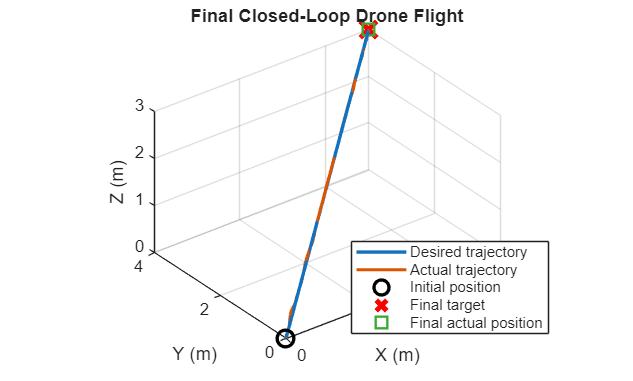



%% ========================================================
% 3. BASIC MODEL PARAMETERS
% ========================================================

% Same mass used in Step 6

m = 1.0;                       % kg

g_value = 9.81;                % m/s^2

hover_thrust = m*g_value;


%% ========================================================
% PART A
% TRAJECTORY PERFORMANCE
% ========================================================


%% --------------------------------------------------------
% 4. Total reference trajectory distance
% --------------------------------------------------------

trajectory_distance = 0;

for k = 1:numSamples-1

    trajectory_distance = ...
        trajectory_distance + ...
        norm(pd(k+1,:) - pd(k,:));

end


%% --------------------------------------------------------
% 5. Desired velocity and acceleration statistics
% --------------------------------------------------------

desired_speed = ...
    vecnorm(vd,2,2);

desired_acceleration = ...
    vecnorm(ad,2,2);


maximum_speed = ...
    max(desired_speed);


maximum_acceleration = ...
    max(desired_acceleration);


%% --------------------------------------------------------
% 6. Final desired trajectory values
% --------------------------------------------------------

final_desired_position = ...
    pd(end,:);

final_desired_velocity = ...
    vd(end,:);

final_desired_acceleration = ...
    ad(end,:);


%% ========================================================
% PART B
% STATE ESTIMATION PERFORMANCE
% ========================================================


%% --------------------------------------------------------
% 7. EKF position estimation error
% --------------------------------------------------------

ekf_position_error = ...
    p_est_history - p_history;

ekf_position_error_norm = ...
    vecnorm(ekf_position_error,2,2);


ekf_position_RMSE = ...
    sqrt(mean(ekf_position_error.^2,1));


ekf_position_total_RMSE = ...
    sqrt(mean(ekf_position_error_norm.^2));


ekf_position_max_error = ...
    max(ekf_position_error_norm);


ekf_position_final_error = ...
    ekf_position_error_norm(end);


%% --------------------------------------------------------
% 8. EKF velocity estimation error
% --------------------------------------------------------

ekf_velocity_error = ...
    v_est_history - v_history;


ekf_velocity_RMSE = ...
    sqrt(mean(ekf_velocity_error.^2,1));


ekf_velocity_error_norm = ...
    vecnorm(ekf_velocity_error,2,2);


%% --------------------------------------------------------
% 9. Camera measurement error
% --------------------------------------------------------

camera_error = ...
    p_camera_history - p_history;


camera_RMSE = ...
    sqrt(mean(camera_error.^2,1));


camera_error_norm = ...
    vecnorm(camera_error,2,2);


camera_max_error = ...
    max(camera_error_norm);


%% --------------------------------------------------------
% 10. EKF attitude estimation error
% --------------------------------------------------------

ekf_attitude_error = ...
    zeros(numSamples,1);


for k = 1:numSamples

    R_actual = ...
        R_history(:,:,k);

    R_est = ...
        R_est_history(:,:,k);


    R_error = ...
        R_actual' * R_est;


    cos_theta = ...
        (trace(R_error)-1)/2;


    cos_theta = ...
        max(-1,min(1,cos_theta));


    ekf_attitude_error(k) = ...
        acos(cos_theta);

end


ekf_attitude_RMSE = ...
    sqrt(mean(ekf_attitude_error.^2));


%% ========================================================
% PART C
% ACTUAL DRONE TRACKING
% ========================================================


%% --------------------------------------------------------
% 11. Position tracking error
%
% e_p = p_d - p_actual
% --------------------------------------------------------

position_tracking_error = ...
    pd - p_history;


position_tracking_error_norm = ...
    vecnorm(position_tracking_error,2,2);


position_tracking_RMSE = ...
    sqrt(mean(position_tracking_error.^2,1));


position_tracking_total_RMSE = ...
    sqrt(mean(position_tracking_error_norm.^2));


maximum_position_tracking_error = ...
    max(position_tracking_error_norm);


final_position_tracking_error = ...
    position_tracking_error_norm(end);


%% --------------------------------------------------------
% 12. Velocity tracking error
% --------------------------------------------------------

velocity_tracking_error = ...
    vd - v_history;


velocity_tracking_error_norm = ...
    vecnorm(velocity_tracking_error,2,2);


velocity_tracking_RMSE = ...
    sqrt(mean(velocity_tracking_error.^2,1));


final_velocity_error = ...
    velocity_tracking_error_norm(end);


%% --------------------------------------------------------
% 13. Actual final position
% --------------------------------------------------------

final_actual_position = ...
    p_history(end,:);


final_actual_velocity = ...
    v_history(end,:);


%% --------------------------------------------------------
% 14. Final target error vector
% --------------------------------------------------------

final_target_error_vector = ...
    pf - final_actual_position;


final_target_error = ...
    norm(final_target_error_vector);


%% ========================================================
% PART D
% ATTITUDE TRACKING
% ========================================================


%% --------------------------------------------------------
% 15. SO(3) attitude tracking error
% --------------------------------------------------------

attitude_tracking_error = ...
    zeros(numSamples,1);


attitude_tracking_vector = ...
    zeros(numSamples,3);


for k = 1:numSamples

    Rd = ...
        R_desired_history(:,:,k);

    R_actual = ...
        R_history(:,:,k);


    R_error = ...
        Rd' * R_actual;


    cos_theta = ...
        (trace(R_error)-1)/2;


    cos_theta = ...
        max(-1,min(1,cos_theta));


    theta = ...
        acos(cos_theta);


    attitude_tracking_error(k) = ...
        theta;


    if theta > 1e-8

        attitude_tracking_vector(k,:) = ...
            ( ...
            theta/(2*sin(theta)) * ...
            [ ...
            R_error(3,2)-R_error(2,3), ...
            R_error(1,3)-R_error(3,1), ...
            R_error(2,1)-R_error(1,2) ...
            ] ...
            )';

    end

end


attitude_tracking_RMSE = ...
    sqrt(mean(attitude_tracking_error.^2));


final_attitude_error = ...
    attitude_tracking_error(end);


%% ========================================================
% PART E
% CONTROLLER PERFORMANCE
% ========================================================


%% --------------------------------------------------------
% 16. Thrust statistics
% --------------------------------------------------------

maximum_thrust = ...
    max(desired_thrust);


minimum_thrust = ...
    min(desired_thrust);


average_thrust = ...
    mean(desired_thrust);


thrust_RMS = ...
    sqrt(mean(desired_thrust.^2));


thrust_deviation = ...
    desired_thrust - hover_thrust;


maximum_thrust_deviation = ...
    max(abs(thrust_deviation));


%% --------------------------------------------------------
% 17. Torque statistics
% --------------------------------------------------------

maximum_torque = ...
    max(abs(torque_command),[],1);


RMS_torque = ...
    sqrt(mean(torque_command.^2,1));


total_torque_RMS = ...
    sqrt(mean(vecnorm(torque_command,2,2).^2));


%% ========================================================
% PART F
% SO(3) NUMERICAL VALIDITY
% ========================================================


%% --------------------------------------------------------
% 18. Maximum orthogonality error
% --------------------------------------------------------

maximum_orthogonality_error = ...
    max(rotation_orthogonality_error);


%% --------------------------------------------------------
% 19. Maximum determinant error
% --------------------------------------------------------

maximum_determinant_error = ...
    max(rotation_determinant_error);


%% ========================================================
% PART G
% FINAL 3D TRAJECTORY
% ========================================================

figure('Name','Final 3D Drone Trajectory');

plot3( ...
    pd(:,1), ...
    pd(:,2), ...
    pd(:,3), ...
    'LineWidth',2);

hold on;


plot3( ...
    p_history(:,1), ...
    p_history(:,2), ...
    p_history(:,3), ...
    'LineWidth',1.8);


% Start point

plot3( ...
    p0(1), ...
    p0(2), ...
    p0(3), ...
    'ko', ...
    'MarkerSize',10, ...
    'LineWidth',2);


% Final target

plot3( ...
    pf(1), ...
    pf(2), ...
    pf(3), ...
    'rx', ...
    'MarkerSize',14, ...
    'LineWidth',3);


% Final actual position

plot3( ...
    final_actual_position(1), ...
    final_actual_position(2), ...
    final_actual_position(3), ...
    's', ...
    'MarkerSize',9, ...
    'LineWidth',2);


grid on;

axis equal;

xlabel('X (m)');
ylabel('Y (m)');
zlabel('Z (m)');

title('Final Closed-Loop Drone Flight');

legend( ...
    'Desired trajectory', ...
    'Actual trajectory', ...
    'Initial position', ...
    'Final target', ...
    'Final actual position', ...
    'Location','best');

view(3);


%% ========================================================
% PART H
% 3D TRAJECTORY ERROR VECTORS
% ========================================================


figure('Name','3D Position Tracking Error');

plot3( ...
    position_tracking_error(:,1), ...
    position_tracking_error(:,2), ...
    position_tracking_error(:,3), ...

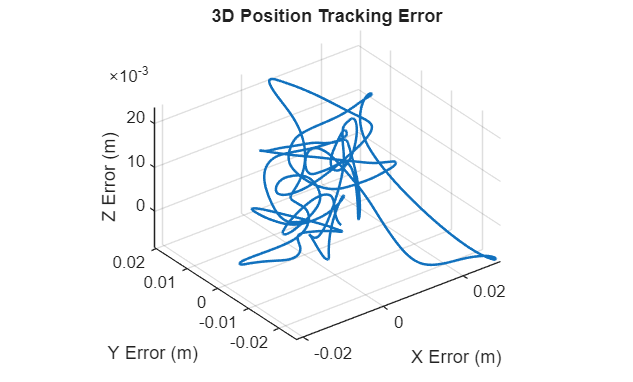

    'LineWidth',1.5);

grid on;

axis equal;

xlabel('X Error (m)');
ylabel('Y Error (m)');
zlabel('Z Error (m)');

title('3D Position Tracking Error');

view(3);

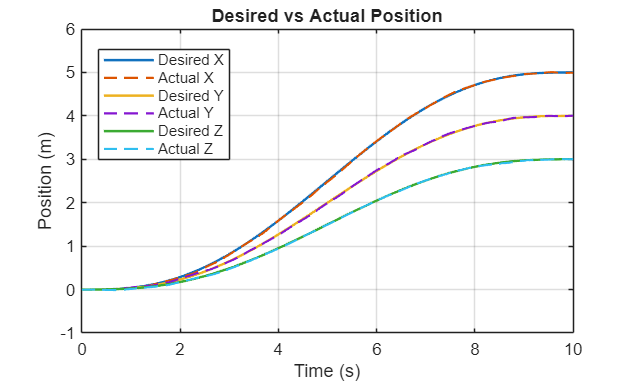



%% ========================================================
% PART I
% DESIRED VS ACTUAL POSITION
% ========================================================


figure('Name','Position Tracking');

plot( ...
    t, ...
    pd(:,1), ...
    'LineWidth',1.5);

hold on;

plot( ...
    t, ...
    p_history(:,1), ...
    '--', ...
    'LineWidth',1.3);

plot( ...
    t, ...
    pd(:,2), ...
    'LineWidth',1.5);

plot( ...
    t, ...
    p_history(:,2), ...
    '--', ...
    'LineWidth',1.3);

plot( ...
    t, ...
    pd(:,3), ...
    'LineWidth',1.5);

plot( ...
    t, ...
    p_history(:,3), ...
    '--', ...
    'LineWidth',1.3);

xlabel('Time (s)');
ylabel('Position (m)');

title('Desired vs Actual Position');

legend( ...
    'Desired X', ...
    'Actual X', ...
    'Desired Y', ...
    'Actual Y', ...
    'Desired Z', ...
    'Actual Z', ...
    'Location','best');

grid on;

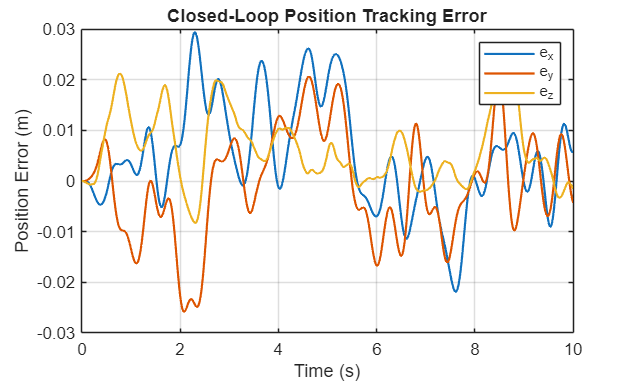



%% ========================================================
% PART J
% POSITION ERROR
% ========================================================


figure('Name','Position Tracking Error');

plot( ...
    t, ...
    position_tracking_error(:,1), ...
    'LineWidth',1.3);

hold on;

plot( ...
    t, ...
    position_tracking_error(:,2), ...
    'LineWidth',1.3);

plot( ...
    t, ...
    position_tracking_error(:,3), ...
    'LineWidth',1.3);

xlabel('Time (s)');
ylabel('Position Error (m)');

title('Closed-Loop Position Tracking Error');

legend('e_x','e_y','e_z');

grid on;


%% ========================================================
% PART K
% POSITION ERROR MAGNITUDE
% ========================================================

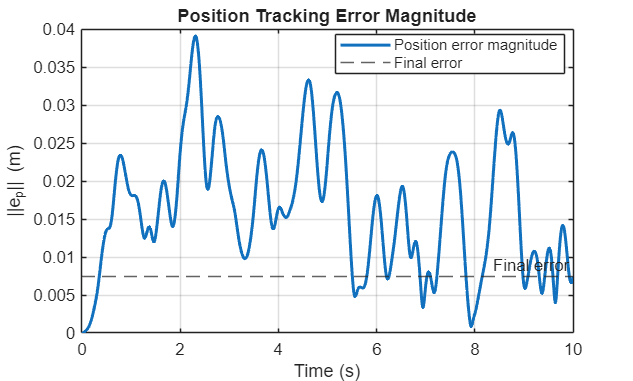



figure('Name','Position Error Magnitude');

plot( ...
    t, ...
    position_tracking_error_norm, ...
    'LineWidth',1.8);

hold on;

yline( ...
    final_position_tracking_error, ...
    '--', ...
    'Final error');

xlabel('Time (s)');
ylabel('||e_p|| (m)');

title('Position Tracking Error Magnitude');

legend( ...
    'Position error magnitude', ...
    'Final error', ...
    'Location','best');

grid on;

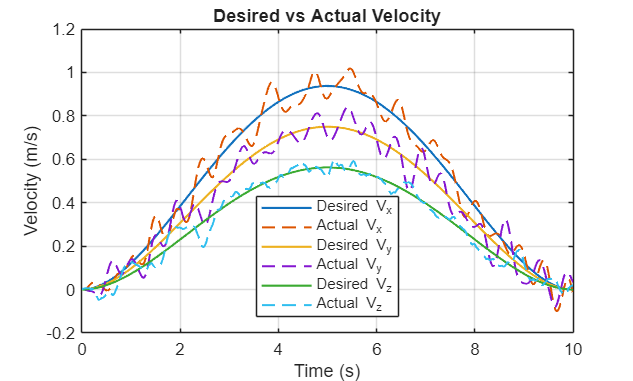



%% ========================================================
% PART L
% DESIRED VS ACTUAL VELOCITY
% ========================================================


figure('Name','Velocity Tracking');

plot( ...
    t, ...
    vd(:,1), ...
    'LineWidth',1.3);

hold on;

plot( ...
    t, ...
    v_history(:,1), ...
    '--', ...
    'LineWidth',1.2);

plot( ...
    t, ...
    vd(:,2), ...
    'LineWidth',1.3);

plot( ...
    t, ...
    v_history(:,2), ...
    '--', ...
    'LineWidth',1.2);

plot( ...
    t, ...
    vd(:,3), ...
    'LineWidth',1.3);

plot( ...
    t, ...
    v_history(:,3), ...
    '--', ...
    'LineWidth',1.2);

xlabel('Time (s)');
ylabel('Velocity (m/s)');

title('Desired vs Actual Velocity');

legend( ...
    'Desired V_x', ...
    'Actual V_x', ...
    'Desired V_y', ...
    'Actual V_y', ...
    'Desired V_z', ...
    'Actual V_z', ...
    'Location','best');

grid on;

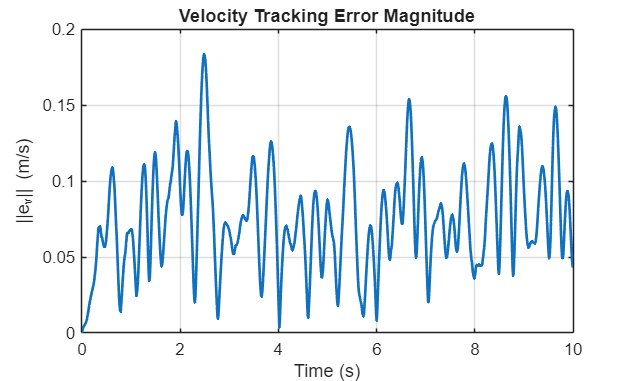



%% ========================================================
% PART M
% VELOCITY ERROR
% ========================================================


figure('Name','Velocity Tracking Error');

plot( ...
    t, ...
    velocity_tracking_error_norm, ...
    'LineWidth',1.6);

xlabel('Time (s)');
ylabel('||e_v|| (m/s)');

title('Velocity Tracking Error Magnitude');

grid on;

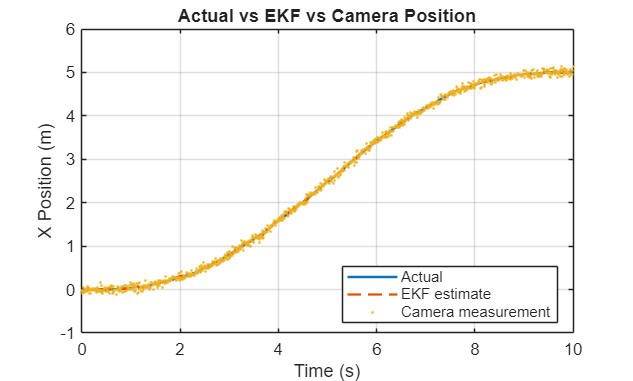



%% ========================================================
% PART N
% EKF: ACTUAL VS ESTIMATED POSITION
% ========================================================


figure('Name','EKF Position Estimation');

plot( ...
    t, ...
    p_history(:,1), ...
    'LineWidth',1.5);

hold on;

plot( ...
    t, ...
    p_est_history(:,1), ...
    '--', ...
    'LineWidth',1.3);

plot( ...
    t, ...
    p_camera_history(:,1), ...
    '.', ...
    'MarkerSize',4);

xlabel('Time (s)');
ylabel('X Position (m)');

title('Actual vs EKF vs Camera Position');

legend( ...
    'Actual', ...
    'EKF estimate', ...
    'Camera measurement', ...
    'Location','best');

grid on;



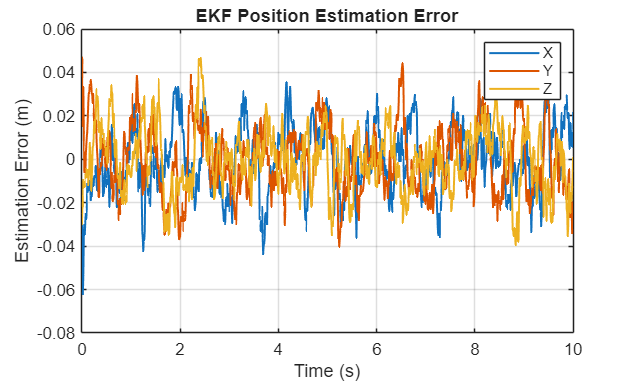

%% ========================================================
% PART O
% EKF POSITION ERROR
% ========================================================


figure('Name','EKF Position Error');

plot( ...
    t, ...
    ekf_position_error(:,1), ...
    'LineWidth',1.2);

hold on;

plot( ...
    t, ...
    ekf_position_error(:,2), ...
    'LineWidth',1.2);

plot( ...
    t, ...
    ekf_position_error(:,3), ...
    'LineWidth',1.2);

xlabel('Time (s)');
ylabel('Estimation Error (m)');

title('EKF Position Estimation Error');

legend('X','Y','Z');

grid on;



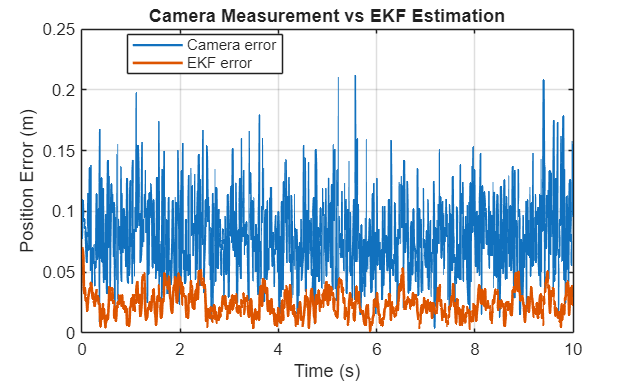

%% ========================================================
% PART P
% CAMERA VS EKF ERROR
% ========================================================


figure('Name','Sensor vs EKF Accuracy');

plot( ...
    t, ...
    camera_error_norm, ...
    'LineWidth',1.3);

hold on;

plot( ...
    t, ...
    ekf_position_error_norm, ...
    'LineWidth',1.6);

xlabel('Time (s)');
ylabel('Position Error (m)');

title('Camera Measurement vs EKF Estimation');

legend( ...
    'Camera error', ...
    'EKF error', ...
    'Location','best');

grid on;


%% ========================================================

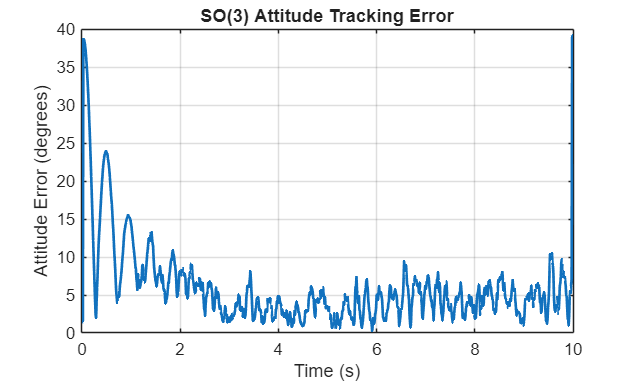

% PART Q
% ATTITUDE TRACKING
% ========================================================


figure('Name','SO3 Attitude Tracking Error');

plot( ...
    t, ...
    rad2deg(attitude_tracking_error), ...
    'LineWidth',1.6);

xlabel('Time (s)');
ylabel('Attitude Error (degrees)');

title('SO(3) Attitude Tracking Error');

grid on;


%% ========================================================
% PART R

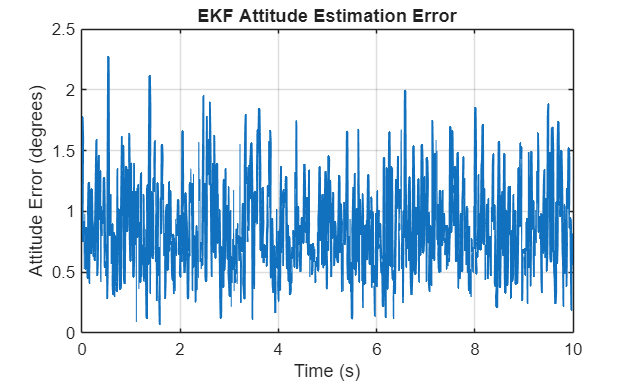

% EKF ATTITUDE ERROR
% ========================================================


figure('Name','EKF Attitude Estimation Error');

plot( ...
    t, ...
    rad2deg(ekf_attitude_error), ...
    'LineWidth',1.5);

xlabel('Time (s)');
ylabel('Attitude Error (degrees)');

title('EKF Attitude Estimation Error');

grid on;

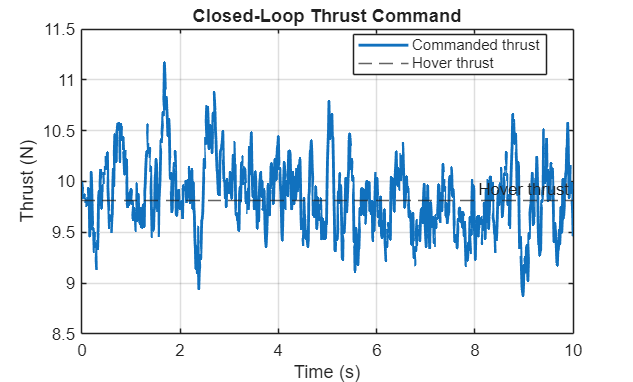



%% ========================================================
% PART S
% THRUST COMMAND
% ========================================================


figure('Name','Thrust Command');

plot( ...
    t, ...
    desired_thrust, ...
    'LineWidth',1.7);

hold on;

yline( ...
    hover_thrust, ...
    '--', ...
    'Hover thrust');

xlabel('Time (s)');
ylabel('Thrust (N)');

title('Closed-Loop Thrust Command');

legend( ...
    'Commanded thrust', ...
    'Hover thrust', ...
    'Location','best');

grid on;


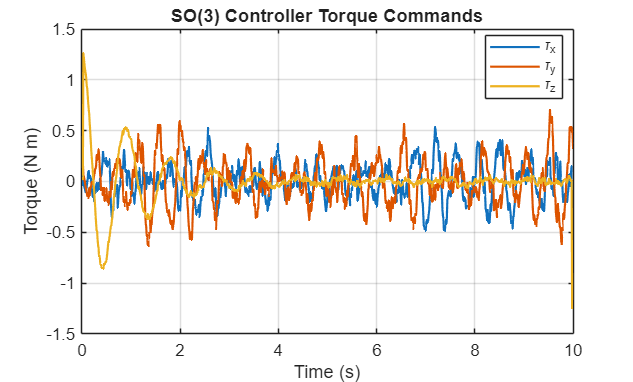


%% ========================================================
% PART T
% TORQUE COMMAND
% ========================================================


figure('Name','SO3 Torque Commands');

plot( ...
    t, ...
    torque_command(:,1), ...
    'LineWidth',1.3);

hold on;

plot( ...
    t, ...
    torque_command(:,2), ...
    'LineWidth',1.3);

plot( ...
    t, ...
    torque_command(:,3), ...
    'LineWidth',1.3);

xlabel('Time (s)');
ylabel('Torque (N m)');

title('SO(3) Controller Torque Commands');

legend( ...
    '\tau_x', ...
    '\tau_y', ...
    '\tau_z', ...
    'Location','best');

grid on;


%% ========================================================

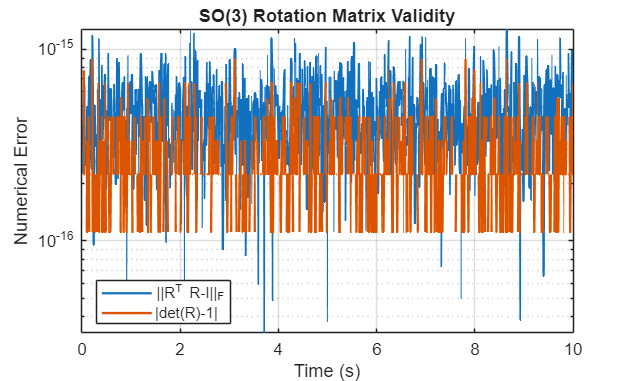

% PART U
% SO(3) NUMERICAL VALIDITY
% ========================================================


figure('Name','SO3 Numerical Validity');

semilogy( ...
    t, ...
    rotation_orthogonality_error, ...
    'LineWidth',1.4);

hold on;

semilogy( ...
    t, ...
    rotation_determinant_error, ...
    'LineWidth',1.4);

xlabel('Time (s)');
ylabel('Numerical Error');

title('SO(3) Rotation Matrix Validity');

legend( ...
    '||R^T R-I||_F', ...
    '|det(R)-1|', ...
    'Location','best');

grid on;

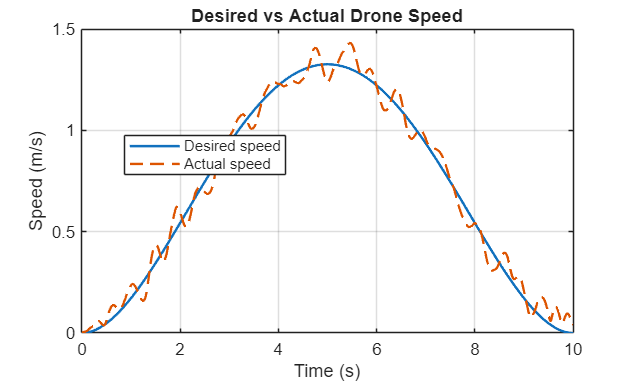



%% ========================================================
% PART V
% FLIGHT SPEED
% ========================================================


actual_speed = ...
    vecnorm(v_history,2,2);


figure('Name','Drone Speed');

plot( ...
    t, ...
    desired_speed, ...
    'LineWidth',1.5);

hold on;

plot( ...
    t, ...
    actual_speed, ...
    '--', ...
    'LineWidth',1.4);

xlabel('Time (s)');
ylabel('Speed (m/s)');

title('Desired vs Actual Drone Speed');

legend( ...
    'Desired speed', ...
    'Actual speed', ...
    'Location','best');

grid on;

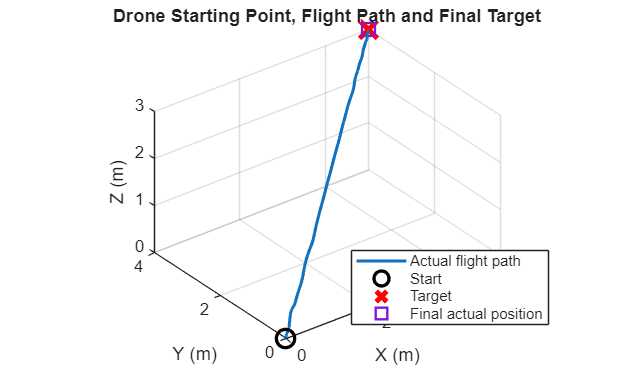



%% ========================================================
% PART W
% FINAL TARGET REACHING SUMMARY
% ========================================================


figure('Name','Final Target Reaching');

plot3( ...
    p_history(:,1), ...
    p_history(:,2), ...
    p_history(:,3), ...
    'LineWidth',1.8);

hold on;

plot3( ...
    p0(1), ...
    p0(2), ...
    p0(3), ...
    'ko', ...
    'MarkerSize',11, ...
    'LineWidth',2);

plot3( ...
    pf(1), ...
    pf(2), ...
    pf(3), ...
    'rx', ...
    'MarkerSize',15, ...
    'LineWidth',3);

plot3( ...
    final_actual_position(1), ...
    final_actual_position(2), ...
    final_actual_position(3), ...
    's', ...
    'MarkerSize',10, ...
    'LineWidth',2);

grid on;

axis equal;

xlabel('X (m)');
ylabel('Y (m)');
zlabel('Z (m)');

title('Drone Starting Point, Flight Path and Final Target');

legend( ...
    'Actual flight path', ...
    'Start', ...
    'Target', ...
    'Final actual position', ...
    'Location','best');

view(3);

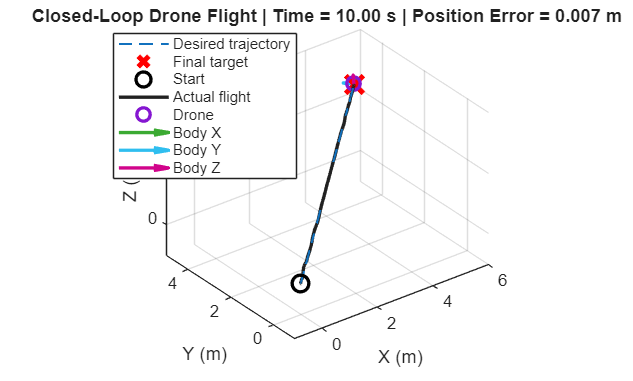



%% ========================================================
% PART X
% ANIMATED DRONE FLIGHT
% ========================================================


figure( ...
    'Name','Drone Flight Animation', ...
    'Color','w');


hold on;

grid on;

axis equal;

xlabel('X (m)');
ylabel('Y (m)');
zlabel('Z (m)');

title('Closed-Loop Autonomous Drone Flight');

% Fixed axes

all_x = [
    pd(:,1);
    p_history(:,1)
];

all_y = [
    pd(:,2);
    p_history(:,2)
];

all_z = [
    pd(:,3);
    p_history(:,3)
];


margin = 1;


xlim([
    min(all_x)-margin ...
    max(all_x)+margin
]);

ylim([
    min(all_y)-margin ...
    max(all_y)+margin
]);

zlim([
    min(all_z)-margin ...
    max(all_z)+margin
]);


% Desired trajectory

plot3( ...
    pd(:,1), ...
    pd(:,2), ...
    pd(:,3), ...
    '--', ...
    'LineWidth',1.2);


% Target

plot3( ...
    pf(1), ...
    pf(2), ...
    pf(3), ...
    'rx', ...
    'MarkerSize',15, ...
    'LineWidth',3);


% Start

plot3( ...
    p0(1), ...
    p0(2), ...
    p0(3), ...
    'ko', ...
    'MarkerSize',10, ...
    'LineWidth',2);


% Actual flight trace

actual_trace = animatedline( ...
    'LineWidth',2);


% Drone center

drone_body = plot3( ...
    p_history(1,1), ...
    p_history(1,2), ...
    p_history(1,3), ...
    'o', ...
    'MarkerSize',8, ...
    'LineWidth',2);


% Body axes

axis_length = 0.35;


drone_x_axis = quiver3( ...
    p_history(1,1), ...
    p_history(1,2), ...
    p_history(1,3), ...
    axis_length, ...
    0, ...
    0, ...
    'LineWidth',2, ...
    'MaxHeadSize',0.8);


drone_y_axis = quiver3( ...
    p_history(1,1), ...
    p_history(1,2), ...
    p_history(1,3), ...
    0, ...
    axis_length, ...
    0, ...
    'LineWidth',2, ...
    'MaxHeadSize',0.8);


drone_z_axis = quiver3( ...
    p_history(1,1), ...
    p_history(1,2), ...
    p_history(1,3), ...
    0, ...
    0, ...
    axis_length, ...
    'LineWidth',2, ...
    'MaxHeadSize',0.8);


legend( ...
    'Desired trajectory', ...
    'Final target', ...
    'Start', ...
    'Actual flight', ...
    'Drone', ...
    'Body X', ...
    'Body Y', ...
    'Body Z', ...
    'Location','best');


view(3);


%% --------------------------------------------------------
% Animation
% ---------------------------------------------------------

animation_step = max(1,round(0.05/dt));


for k = 1:animation_step:numSamples

    p_current = ...
        p_history(k,:);


    R_current = ...
        R_history(:,:,k);


    % Update trace

    addpoints( ...
        actual_trace, ...
        p_current(1), ...
        p_current(2), ...
        p_current(3));



    % Update drone center

    set( ...
        drone_body, ...
        'XData',p_current(1), ...
        'YData',p_current(2), ...
        'ZData',p_current(3));


    % Body X axis

    x_axis = ...
        R_current(:,1) * axis_length;


    set( ...
        drone_x_axis, ...
        'XData',p_current(1), ...
        'YData',p_current(2), ...
        'ZData',p_current(3), ...
        'UData',x_axis(1), ...
        'VData',x_axis(2), ...
        'WData',x_axis(3));


    % Body Y axis

    y_axis = ...
        R_current(:,2) * axis_length;


    set( ...
        drone_y_axis, ...
        'XData',p_current(1), ...
        'YData',p_current(2), ...
        'ZData',p_current(3), ...
        'UData',y_axis(1), ...
        'VData',y_axis(2), ...
        'WData',y_axis(3));


    % Body Z axis

    z_axis = ...
        R_current(:,3) * axis_length;


    set( ...
        drone_z_axis, ...
        'XData',p_current(1), ...
        'YData',p_current(2), ...
        'ZData',p_current(3), ...
        'UData',z_axis(1), ...
        'VData',z_axis(2), ...
        'WData',z_axis(3));


    title(sprintf( ...
        'Closed-Loop Drone Flight | Time = %.2f s | Position Error = %.3f m', ...
        t(k), ...
        position_tracking_error_norm(k)));


    drawnow;


    pause(0.01);

end


%% ========================================================
% PART Y
% OPTIONAL VIDEO RECORDING
% ========================================================

% To create a MATLAB video of the animation:
%
% Uncomment the following section.
%
% writerObj = VideoWriter('drone_closed_loop_flight.mp4','MPEG-4');
% writerObj.FrameRate = 20;
% open(writerObj);
%
% for k = 1:animation_step:numSamples
%
%     % Update graphics exactly as above
%     % frame = getframe(gcf);
%     % writeVideo(writerObj,frame);
%
% end
%
% close(writerObj);


%% ========================================================
% PART Z
% FINAL NUMERICAL SUMMARY
% ========================================================


fprintf('\n');
fprintf('========================================================\n');
fprintf('          COMPLETE DRONE TOY MODEL RESULTS\n');
fprintf('========================================================\n');


          COMPLETE DRONE TOY MODEL RESULTS



%% --------------------------------------------------------
% Input
% ---------------------------------------------------------

fprintf('\nINPUT / TARGET\n');
fprintf('--------------------------------------------------------\n');

fprintf( ...
    'Initial position = [%.3f %.3f %.3f] m\n', ...
    p0(1),p0(2),p0(3));


INPUT / TARGET


--------------------------------------------------------


Initial position = [0.000 0.000 0.000] m




fprintf( ...
    'Final target     = [%.3f %.3f %.3f] m\n', ...
    pf(1),pf(2),pf(3));


fprintf( ...
    'Flight duration  = %.3f s\n', ...
    t(end));


Final target     = [5.000 4.000 3.000] m


Flight duration  = 10.000 s



fprintf( ...
    'Simulation dt    = %.4f s\n', ...
    dt);


fprintf( ...
    'Trajectory samples = %d\n', ...
    numSamples);


%% --------------------------------------------------------

Simulation dt    = 0.0100 s


Trajectory samples = 1001


% Trajectory
% ---------------------------------------------------------

fprintf('\nTRAJECTORY GENERATION\n');


TRAJECTORY GENERATION


fprintf('--------------------------------------------------------\n');

--------------------------------------------------------



fprintf( ...
    'Trajectory distance = %.4f m\n', ...
    trajectory_distance);

Trajectory distance = 7.0711 m




fprintf( ...
    'Maximum desired speed = %.4f m/s\n', ...
    maximum_speed);


fprintf( ...
    'Maximum desired acceleration = %.4f m/s^2\n', ...
    maximum_acceleration);


fprintf( ...
    'Final desired velocity magnitude = %.4e m/s\n', ...
    norm(final_desired_velocity));


fprintf( ...
    'Final desired acceleration magnitude = %.4e m/s^2\n', ...
    norm(final_desired_acceleration));


%% --------------------------------------------------------
% Camera
% ---------------------------------------------------------

fprintf('\nCAMERA MEASUREMENT\n');
fprintf('--------------------------------------------------------\n');

fprintf( ...
    'Camera RMSE X = %.4f m\n', ...
    camera_RMSE(1));


fprintf( ...
    'Camera RMSE Y = %.4f m\n', ...
    camera_RMSE(2));


fprintf( ...
    'Camera RMSE Z = %.4f m\n', ...
    camera_RMSE(3));


fprintf( ...
    'Maximum camera error = %.4f m\n', ...
    camera_max_error);


%% --------------------------------------------------------
% EKF
% ---------------------------------------------------------

fprintf('\nERROR-STATE EKF\n');
fprintf('--------------------------------------------------------\n');

fprintf( ...
    'EKF position RMSE X = %.4f m\n', ...
    ekf_position_RMSE(1));


fprintf( ...
    'EKF position RMSE Y = %.4f m\n', ...
    ekf_position_RMSE(2));


fprintf( ...
    'EKF position RMSE Z = %.4f m\n', ...
    ekf_position_RMSE(3));


fprintf( ...
    'EKF total position RMSE = %.4f m\n', ...
    ekf_position_total_RMSE);


fprintf( ...
    'Maximum EKF position error = %.4f m\n', ...
    ekf_position_max_error);


fprintf( ...
    'Final EKF position error = %.4f m\n', ...
    ekf_position_final_error);


fprintf( ...
    'EKF velocity RMSE = [%.4f %.4f %.4f] m/s\n', ...
    ekf_velocity_RMSE(1), ...
    ekf_velocity_RMSE(2), ...
    ekf_velocity_RMSE(3));

Maximum desired speed = 1.3258 m/s


Maximum desired acceleration = 0.4082 m/s^2


Final desired velocity magnitude = 3.6977e-15 m/s


Final desired acceleration magnitude = 1.1144e-15 m/s^2



CAMERA MEASUREMENT


--------------------------------------------------------


Camera RMSE X = 0.0512 m


Camera RMSE Y = 0.0499 m


Camera RMSE Z = 0.0492 m


Maximum camera error = 0.2111 m



ERROR-STATE EKF


--------------------------------------------------------


EKF position RMSE X = 0.0152 m


EKF position RMSE Y = 0.0158 m


EKF position RMSE Z = 0.0143 m


EKF total position RMSE = 0.0262 m


Maximum EKF position error = 0.0700 m


Final EKF position error = 0.0295 m


EKF velocity RMSE = [0.0661 0.0691 0.0635] m/s




fprintf( ...
    'EKF attitude RMSE = %.4f deg\n', ...
    rad2deg(ekf_attitude_RMSE));

EKF attitude RMSE = 0.9376 deg




%% --------------------------------------------------------
% Controller
% ---------------------------------------------------------

fprintf('\nSO(3) CONTROLLER\n');


SO(3) CONTROLLER


fprintf('--------------------------------------------------------\n');

--------------------------------------------------------



fprintf( ...
    'Hover thrust = %.4f N\n', ...
    hover_thrust);

Hover thrust = 9.8100 N




fprintf( ...
    'Minimum thrust = %.4f N\n', ...
    minimum_thrust);

Minimum thrust = 8.8771 N




fprintf( ...
    'Maximum thrust = %.4f N\n', ...
    maximum_thrust);

Maximum thrust = 11.1692 N




fprintf( ...
    'Average thrust = %.4f N\n', ...
    average_thrust);

Average thrust = 9.8454 N




fprintf( ...
    'Maximum thrust deviation from hover = %.4f N\n', ...
    maximum_thrust_deviation);

Maximum thrust deviation from hover = 1.3592 N




fprintf( ...
    'Maximum torque = [%.4f %.4f %.4f] N m\n', ...
    maximum_torque(1), ...
    maximum_torque(2), ...
    maximum_torque(3));

Maximum torque = [0.5329 0.7033 1.2635] N m




fprintf( ...
    'Torque RMS = [%.4f %.4f %.4f] N m\n', ...
    RMS_torque(1), ...
    RMS_torque(2), ...
    RMS_torque(3));



Torque RMS = [0.1754 0.2301 0.2150] N m


%% --------------------------------------------------------
% Actual flight
% ---------------------------------------------------------

fprintf('\nACTUAL CLOSED-LOOP FLIGHT\n');


ACTUAL CLOSED-LOOP FLIGHT


fprintf('--------------------------------------------------------\n');

--------------------------------------------------------



fprintf( ...
    'Final actual position = [%.4f %.4f %.4f] m\n', ...
    final_actual_position(1), ...
    final_actual_position(2), ...
    final_actual_position(3));

Final actual position = [4.9942 4.0043 3.0015] m




fprintf( ...
    'Final actual velocity = [%.4f %.4f %.4f] m/s\n', ...
    final_actual_velocity(1), ...
    final_actual_velocity(2), ...
    final_actual_velocity(3));

Final actual velocity = [-0.0208 0.0342 0.0161] m/s




fprintf( ...
    'Final target error = %.4f m\n', ...
    final_target_error);

Final target error = 0.0074 m




fprintf( ...
    'Position RMSE = [%.4f %.4f %.4f] m\n', ...
    position_tracking_RMSE(1), ...
    position_tracking_RMSE(2), ...
    position_tracking_RMSE(3));


Position RMSE = [0.0116 0.0105 0.0095] m



fprintf( ...
    'Total position RMSE = %.4f m\n', ...
    position_tracking_total_RMSE);


Total position RMSE = 0.0183 m



fprintf( ...
    'Maximum position tracking error = %.4f m\n', ...
    maximum_position_tracking_error);


Maximum position tracking error = 0.0391 m



fprintf( ...
    'Final velocity error = %.4f m/s\n', ...
    final_velocity_error);


Final velocity error = 0.0431 m/s



fprintf( ...
    'Velocity RMSE = [%.4f %.4f %.4f] m/s\n', ...
    velocity_tracking_RMSE(1), ...
    velocity_tracking_RMSE(2), ...
    velocity_tracking_RMSE(3));

Velocity RMSE = [0.0512 0.0554 0.0329] m/s




fprintf( ...
    'Attitude tracking RMSE = %.4f deg\n', ...
    rad2deg(attitude_tracking_RMSE));


Attitude tracking RMSE = 8.0916 deg



fprintf( ...
    'Final attitude error = %.4f deg\n', ...
    rad2deg(final_attitude_error));


Final attitude error = 38.6393 deg



%% --------------------------------------------------------
% Mathematical validity
% ---------------------------------------------------------

fprintf('\nSO(3) NUMERICAL VALIDITY\n');


SO(3) NUMERICAL VALIDITY


fprintf('--------------------------------------------------------\n');

--------------------------------------------------------



fprintf( ...
    'Maximum ||R^T R-I||_F = %.4e\n', ...
    maximum_orthogonality_error);

Maximum ||R^T R-I||_F = 1.2773e-15




fprintf( ...
    'Maximum |det(R)-1| = %.4e\n', ...
    maximum_determinant_error);

Maximum |det(R)-1| = 8.8818e-16




fprintf('\n');
fprintf('========================================================\n');
fprintf('                 STEP 7 COMPLETE\n');
fprintf('========================================================\n');

                 STEP 7 COMPLETE




%% ========================================================
% SAVE FINAL METRICS
% ========================================================

save( ...
    'drone_toy_model.mat', ...
    'trajectory_distance', ...
    'maximum_speed', ...
    'maximum_acceleration', ...
    'camera_RMSE', ...
    'camera_error_norm', ...
    'ekf_position_error', ...
    'ekf_position_error_norm', ...
    'ekf_position_RMSE', ...
    'ekf_position_total_RMSE', ...
    'ekf_position_max_error', ...
    'ekf_position_final_error', ...
    'ekf_velocity_error', ...
    'ekf_velocity_RMSE', ...
    'ekf_attitude_error', ...
    'ekf_attitude_RMSE', ...
    'position_tracking_error', ...
    'position_tracking_error_norm', ...
    'position_tracking_RMSE', ...
    'position_tracking_total_RMSE', ...
    'maximum_position_tracking_error', ...
    'final_position_tracking_error', ...
    'velocity_tracking_error', ...
    'velocity_tracking_error_norm', ...
    'velocity_tracking_RMSE', ...
    'attitude_tracking_error', ...
    'attitude_tracking_vector', ...
    'attitude_tracking_RMSE', ...
    'final_attitude_error', ...
    'maximum_thrust', ...
    'minimum_thrust', ...
    'average_thrust', ...
    'thrust_RMS', ...
    'thrust_deviation', ...
    'maximum_thrust_deviation', ...
    'maximum_torque', ...
    'RMS_torque', ...
    'total_torque_RMS', ...
    'maximum_orthogonality_error', ...
    'maximum_determinant_error', ...
    'final_target_error', ...
    'final_actual_position', ...
    'final_actual_velocity');

fprintf('\nFinal evaluation metrics saved to drone_toy_model.mat\n');


Final evaluation metrics saved to drone_toy_model.mat
